%--------------------------
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";

rowNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
rowNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
rowNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
colNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
colNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];

%-----------------------------------
% Exp3
%-----------------------------------
Exp3RowMatrix = zeros(4, 30);

%indivsual folder
dirInfo1 = dir(resultpath);
FolderNames1 = {dirInfo1(~ismember({dirInfo1(:).name}, {'.', '..'})).name};
numFolders1 = sum(~ismember({dirInfo1(:).name}, {'.', '..'}));

%indivisual name
subject_name = {};

for foldernum1 = 1:numFolders1
    namefolder = fullfile(resultpath, FolderNames1{foldernum1});

    %exp data
    dirInfo2 = dir(namefolder);
    FileNames2 = {dirInfo2(~ismember({dirInfo2(:).name}, {'.', '..'})).name};
    numFile2 = sum(~ismember({dirInfo2(:).name}, {'.', '..'}));
    for foldernum2 = 1:numFile2
        datafile = fullfile(namefolder,FileNames2{foldernum2});
        disp(datafile);

        csvData = readtable(datafile,'ReadVariableNames', true,'VariableNamingRule','preserve');
        headers = readtable(datafile,'VariableNamingRule','preserve').Properties.VariableNames;
        avscore = reshape(mean(csvData{:,:},1),1,[]);

        %words
        words = split(FileNames2{foldernum2},{'_', '.'});
        if ~any(strcmp(subject_name,words{1}))
            subject_name{end + 1} = words{1};
        end

        for i = 1:length(headers)
            nameStr = headers{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames,words{2}));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                Exp3RowMatrix(rowIndex, colIndex) = Exp3RowMatrix(rowIndex, colIndex) + avscore(i);
            end
        end
    end
end

.\results\Jiang\Jiang_cu0025_boardA.csv
.\results\Jiang\Jiang_cu0025_boardB.csv
.\results\Jiang\Jiang_cu0025_boardC.csv
.\results\Jiang\Jiang_cu0025_bunny.csv
.\results\Jiang\Jiang_cu0025_dragon.csv
.\results\Jiang\Jiang_cu0025_sphere.csv
.\results\Jiang\Jiang_cu0129_boardA.csv
.\results\Jiang\Jiang_cu0129_boardB.csv
.\results\Jiang\Jiang_cu0129_boardC.csv
.\results\Jiang\Jiang_cu0129_bunny.csv
.\results\Jiang\Jiang_cu0129_dragon.csv
.\results\Jiang\Jiang_cu0129_sphere.csv
.\results\Jiang\Jiang_pla0075_boardA.csv
.\results\Jiang\Jiang_pla0075_boardB.csv
.\results\Jiang\Jiang_pla0075_boardC.csv
.\results\Jiang\Jiang_pla0075_bunny.csv
.\results\Jiang\Jiang_pla0075_dragon.csv
.\results\Jiang\Jiang_pla0075_sphere.csv
.\results\Jiang\jiang_pla0225_boardA.csv
.\results\Jiang\jiang_pla0225_boardB.csv
.\results\Jiang\jiang_pla0225_boardC.csv
.\results\Jiang\jiang_pla0225_bunny.csv
.\results\Jiang\jiang_pla0225_dragon.csv
.\results\Jiang\jiang_pla0225_sphere.csv
.\results\ODA\ODA_cu0025_boardA.


disp("confirm");

confirm


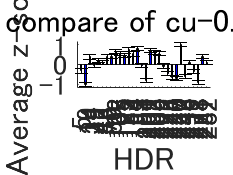

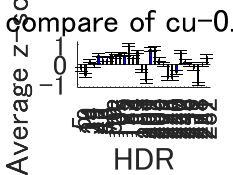

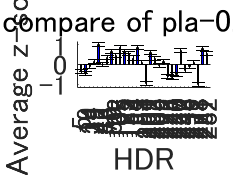

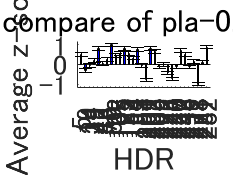



Exp3RowMatrix = Exp3RowMatrix ./ length(subject_name);
Exp3RowMatrix2 = zeros(size(Exp3RowMatrix));
for i = 1:size(Exp3RowMatrix, 1)
    Exp3RowMatrix2(i, :) = zscore(Exp3RowMatrix(i, :));
end

Exp3RowMatrix3 = zeros(size(Exp3RowMatrix2));
for i = 1:size(Exp3RowMatrix2, 1)
    row_min = min(Exp3RowMatrix2(i, :));
    row_max = max(Exp3RowMatrix2(i, :));
    
    Exp3RowMatrix3(i, :) = 2 * (Exp3RowMatrix2(i, :) - row_min) / (row_max - row_min)-1;
end

error_exp3 = std(Exp3RowMatrix3, 0, 2)/ sqrt(size(Exp3RowMatrix3, 2));
error_exp3 = repmat(error_exp3, 1, 30);

%-----------------------------------
% z-score graph
%-----------------------------------

%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    % exp3のプロット
    b3 = bar(x + bar_width/2, Exp3RowMatrix3(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, Exp3RowMatrix3(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' rowNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', rowNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end


%-----------------------------------
% Exp2
%-----------------------------------
%{
resultmitsuba = "resultmitsuba/";
exp2path = "../Exp2/";

Exp2RowMatrix = zeros(4, 15);
%allfileload
dirInfo = dir(exp2path + resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(exp2path + resultmitsuba, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames1)
        sheetName = rowNames1{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames2 == idNum);
            rowIndex = find(strcmp(rowNames1, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                Exp2RowMatrix(rowIndex, colIndex) = Exp2RowMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end
Exp2RowMatrix = Exp2RowMatrix ./ (numFiles*5);

Exp2Row2Matrix = zeros(size(Exp2RowMatrix));
for i = 1:size(Exp2RowMatrix, 1)
    Exp2Row2Matrix(i, :) = zscore(Exp2RowMatrix(i, :));
end

Exp2mitsubaMatrix = zeros(size(Exp2Row2Matrix));
for i = 1:size(Exp2Row2Matrix, 1)
    row_min = min(Exp2Row2Matrix(i, :));
    row_max = max(Exp2Row2Matrix(i, :));
    
    Exp2mitsubaMatrix(i, :) = 2 * (Exp2Row2Matrix(i, :) - row_min) / (row_max - row_min)-1;
end

Exp2mitsuba30mat = zeros(4, 30);
[isMember, colIdx] = ismember(colNames2, colNames);
Exp2mitsuba30mat(:, colIdx(isMember)) = Exp2mitsubaMatrix;

error_exp2 = std(Exp2mitsuba30mat, 0, 2)/ sqrt(size(Exp2mitsuba30mat, 2));
error_exp2 = repmat(error_exp2, 1, 30);

%-----------------------------------
% z-score graph
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    hold on;
    bar_width = 0.35;
    x = 1:length(colNames);

    % exp2のプロット
    b2 = bar(x - bar_width/2, Exp2mitsuba30mat(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', '2D'); 
    h2 = errorbar(x - bar_width/2, Exp2mitsuba30mat(row, :), error_exp2(row,:), 'k', 'linestyle', 'none');

    % exp3のプロット
    b3 = bar(x + bar_width/2, Exp3RowMatrix3(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    h3 = errorbar(x + bar_width/2, Exp3RowMatrix3(row, :), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' rowNames2{row}], 'FontSize', 16);
    legend([b2,b3],{'2D','3D'}, 'Location', 'best');

    plotname = strcat(ana_result, '/', rowNames2{row}, '.jpg');
    saveas(gcf, plotname);
    hold off;
end

%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_exp2 = Exp2mitsuba30mat(row, :);
    data_exp3 = Exp3RowMatrix3(row, :);
    corr_matrix = corrcoef(data_exp2, data_exp3);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);
%}